# Epidemiological Model for COVID19 Pandemic in Colombia

Universidad Nacional de Colombia, July 2020

Authors:

- Juan Diego Ocampo M.

- Carlos Eduardo Aguilar B.

- Sebastián Ruiz T.

- María Camila Muñoz B.

- Sergio Andrés Gerena G.

## 1. Reset Simulation

clc
clearvars
close all
warning('off')

## 2. Problem Guidelines

The code below contains the guidelines given for this assignment alongside with some key parameters to correctly implement the SEIR Compartment Epidemiological model. 

We are told to model the pandemic development in our country and predict when would the virus be contained assuming there is a vaccine for the COVID-19 disease that costs $5 per dose and that Colombia can allocate 10 billion COP per month to buy and administer these vaccines. 

load simbiologyModelResults.mat                                 % Load Simulation Results
totalPopulation = 5.0882891e7;                                  % Total Population (2018)
vaccineEffectiveness = 0.7;                                     % Number between 0.1 and 1
vaccineCost = 5;                                                % Vaccine Cost in USD.
conversionRate = 3617.49;                                       % 1 USD to COP conversion ratio (12/07/2019)
availableBudget = 10e9 / conversionRate                         % Available Budget (in USD)

availableBudget = 2.7643e+06

availableDoses = floor(availableBudget/vaccineCost)             % Available Doses (Vaccine)

availableDoses = 552869

## 3. Data Pre-Processing

This section contains all the code necessary to filter key parameters such as daily and overall recoveries, deaths or cases. This data will be used to visualse the actual pandemic behaviour in our country and determine the model efeectiveness.

### 3.1 Importing Data

Original data source can be checked by clicking [here](http://datosabiertos.esri.co/datasets/782122624f364fbdbd7e287b96c4a358_6/data).

data = importCSV('Colombia_COVID19.csv')

data = 136×7 table
    NUEVOS_CASOS    TOTAL_CASOS    TOTAL_MUERTES    TOTAL_RECUPERADOS    FECHA_ACTUALIZACION    NUEVOS_MUERTOS    NUEVO_RECUPERADOS
    ____________    ___________    _____________    _________________    ___________________    ______________    _________________

          1               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          2               3              0                  0                    N

dailyInfections = data.NUEVOS_CASOS;                                    % Daily Infections
dailyDeaths = data.NUEVOS_MUERTOS;                                      % Daily Fatalities
dailyRecoveries = data.NUEVO_RECUPERADOS;                               % Daily Recoveries
totalInfections = data.TOTAL_CASOS;                                     % Total Infections
totalDeaths = data.TOTAL_MUERTES;                                       % Total Fatalities
totalRecoveries = data.TOTAL_RECUPERADOS;                               % Total Recoveries
susceptiblePopulation = totalInfections - totalRecoveries;              % Infected Remnants
timeElapsed = 1 : length(data.FECHA_ACTUALIZACION);                     % Elapsed Time since Patient Zero (in Days)

### 3.2 Data Visualisation

The code below is used to visualize the variables extracted above as a funcion of time in two ways: cumulative and daily progression for the infected population as well as the recovered and the dead.

#### 3.2.1. Data Visualization (Daily Progression)

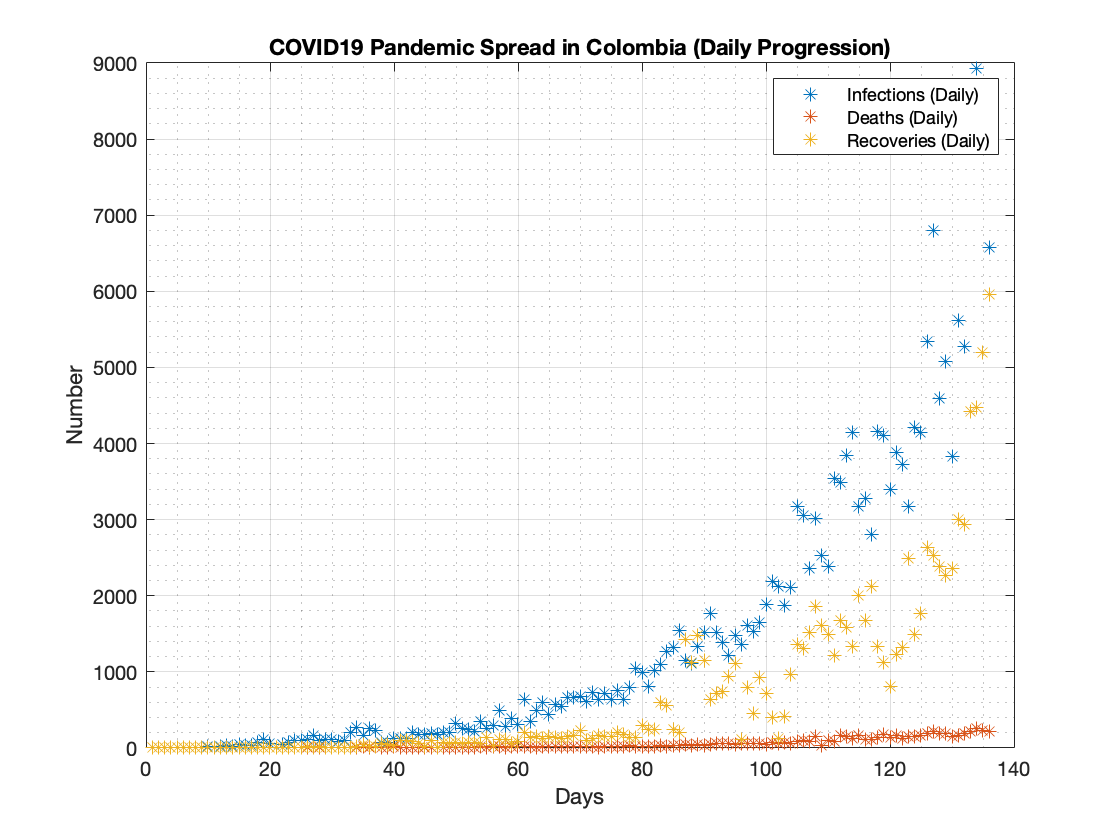

figure;
plot(timeElapsed,dailyInfections,'*',timeElapsed,dailyDeaths,'*',timeElapsed, dailyRecoveries,'*', 'LineWidth',0.5)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Days'), ylabel('Number'), title('COVID19 Pandemic Spread in Colombia (Daily Progression)')
legend('Infections (Daily)','Deaths (Daily)','Recoveries (Daily)')
grid on, grid minor

#### 3.2.2. Data Visualization (Cumulative)

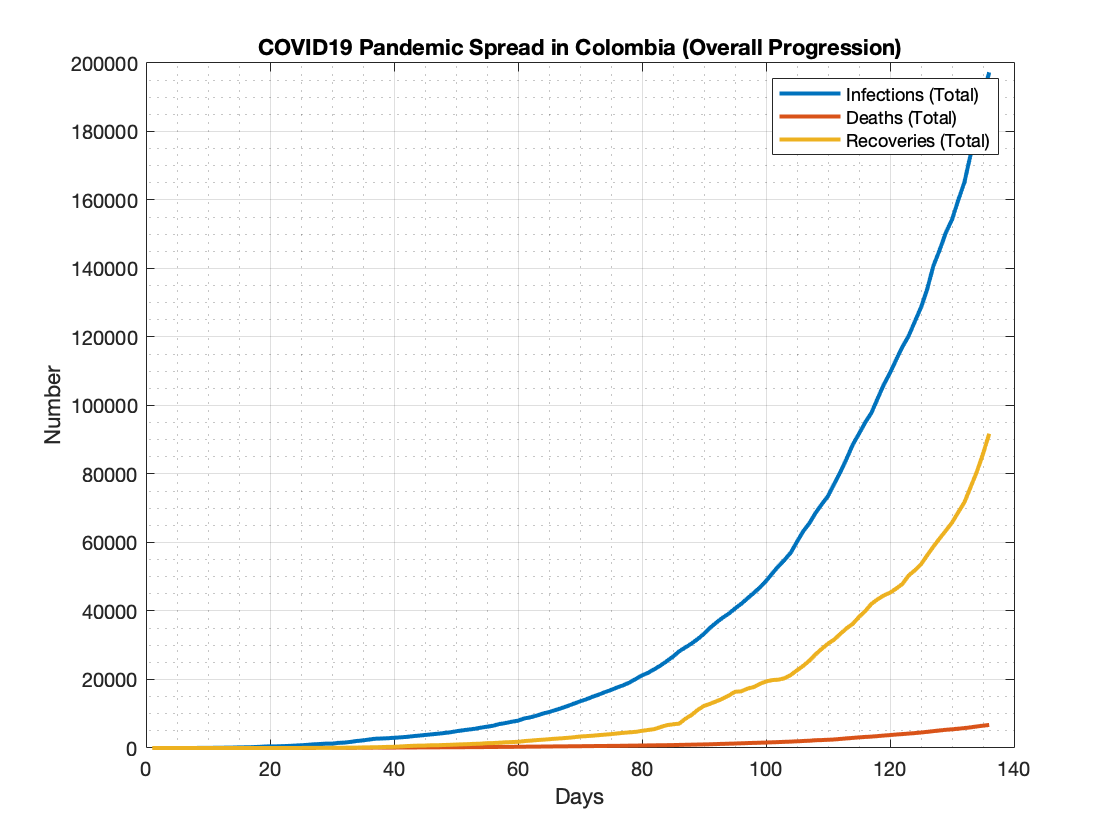

figure;
plot(timeElapsed,totalInfections,timeElapsed,totalDeaths,timeElapsed, totalRecoveries, 'LineWidth',2)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Days'), ylabel('Number'), title('COVID19 Pandemic Spread in Colombia (Overall Progression)')
legend('Infections (Total)','Deaths (Total)','Recoveries (Total)')
grid on, grid minor

### 3.3. Fitting Curve to a Fifth Order Gaussian Model

The code below is used to fit the smooth the data retrieved on Section 3.1 using a function called createFit() which was generated with the Curve Fitting MATLAB App. This is to have a better comparison point for the the graph obtained from the SimBiology model and thus make a preciser evaluation of the model. 

#### 3.3.1. Fitted Data Visualization (Daily Progression)

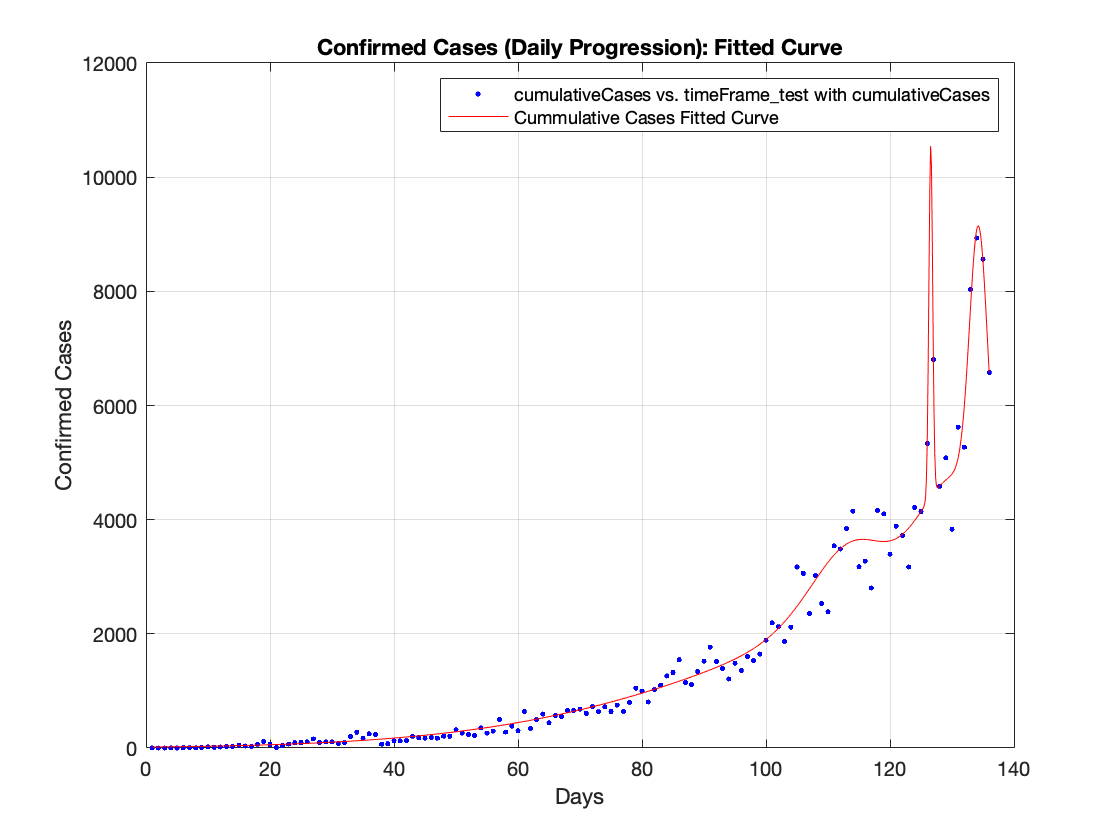

fittedCurve_dailyCases = createFit(timeElapsed, dailyInfections);

xlabel('Days'), ylabel('Confirmed Cases'), title('Confirmed Cases (Daily Progression): Fitted Curve')

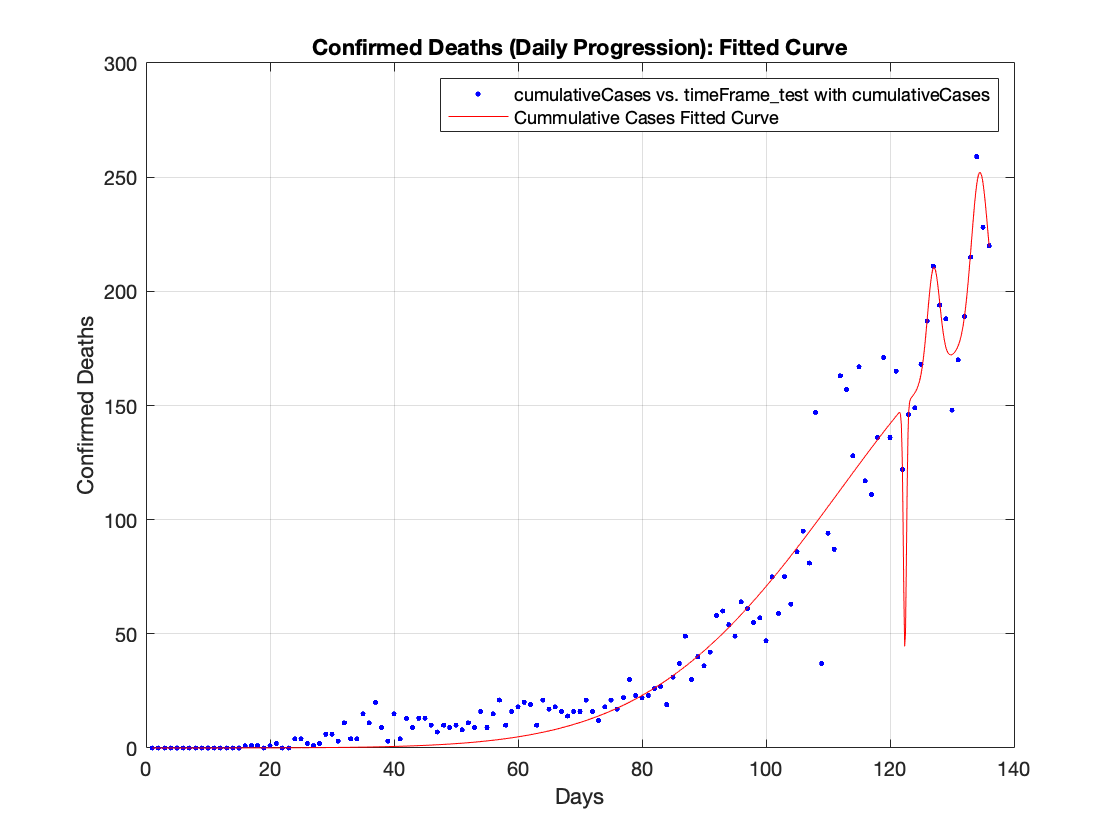

fittedCurve_dailyDeaths = createFit(timeElapsed, dailyDeaths);
xlabel('Days'), ylabel('Confirmed Deaths'), title('Confirmed Deaths (Daily Progression): Fitted Curve')

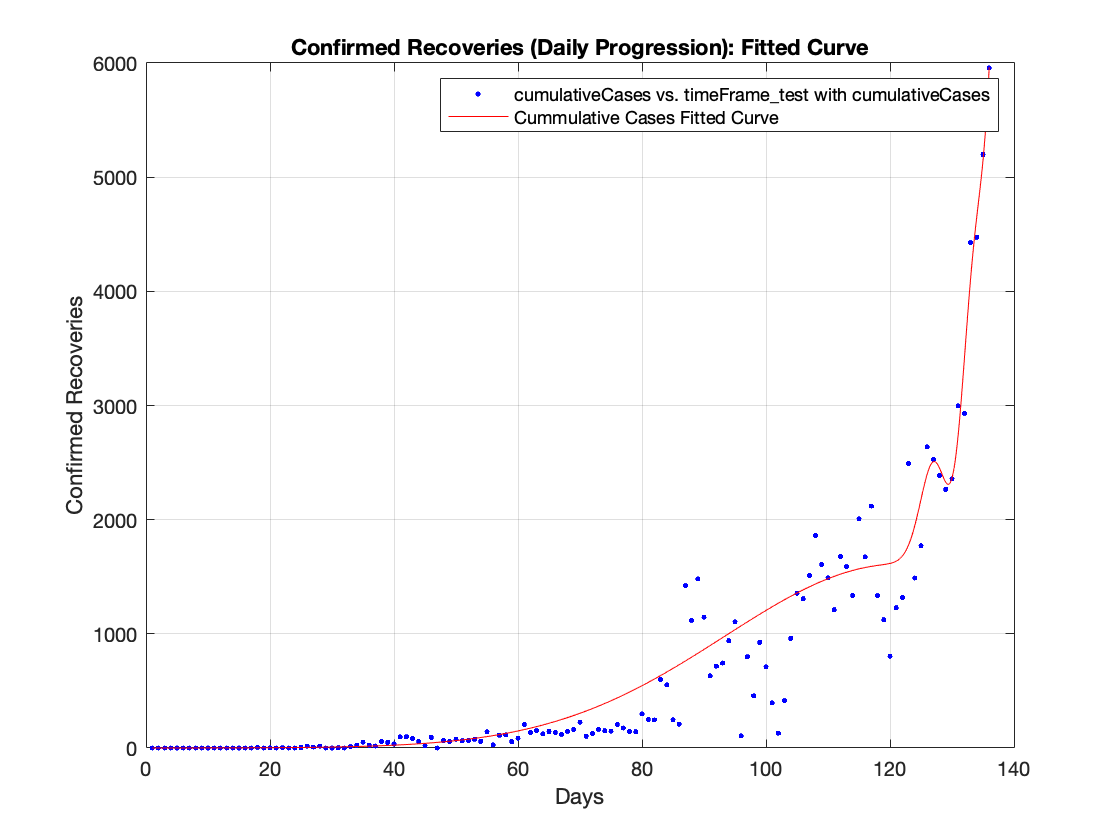

fittedCurve_dailyRecoveries = createFit(timeElapsed, dailyRecoveries);
xlabel('Days'), ylabel('Confirmed Recoveries'), title('Confirmed Recoveries (Daily Progression): Fitted Curve')

#### 3.3.2. Fitted Data Visualization (Daily Progression)

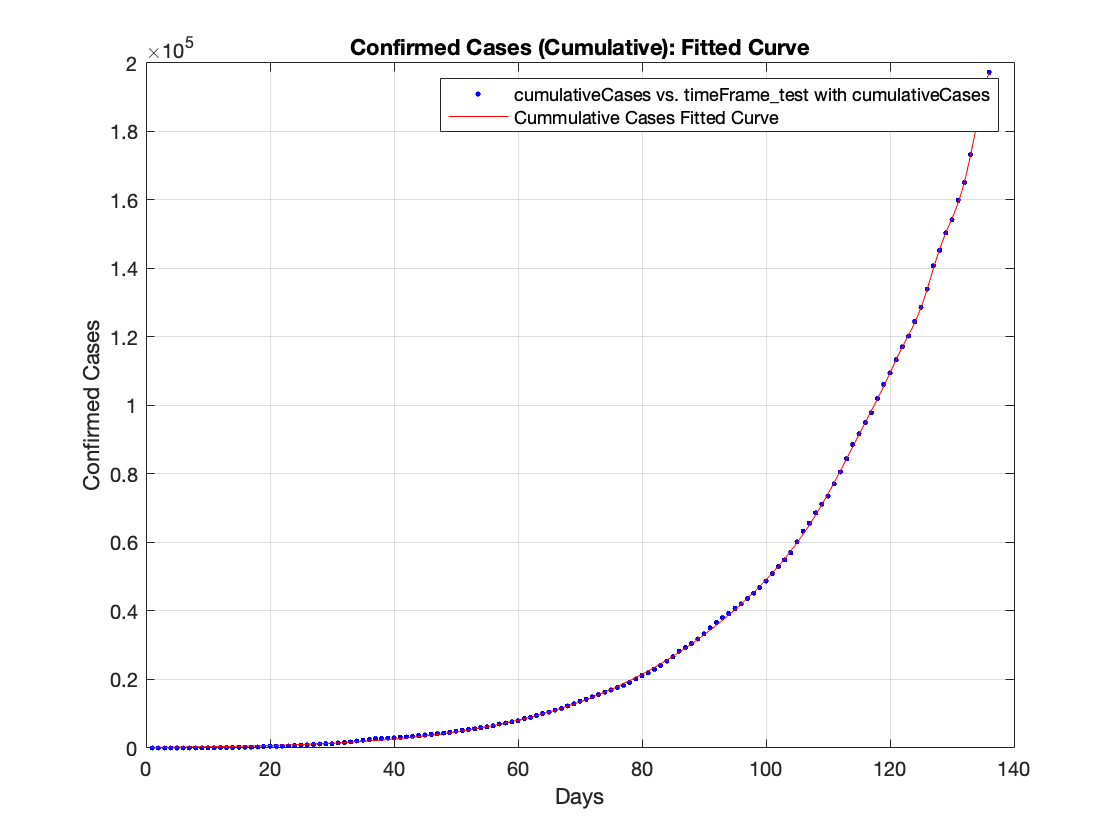

fittedCurve_cumulativeCases = createFit(timeElapsed, totalInfections);
xlabel('Days'), ylabel('Confirmed Cases'), title('Confirmed Cases (Cumulative): Fitted Curve')

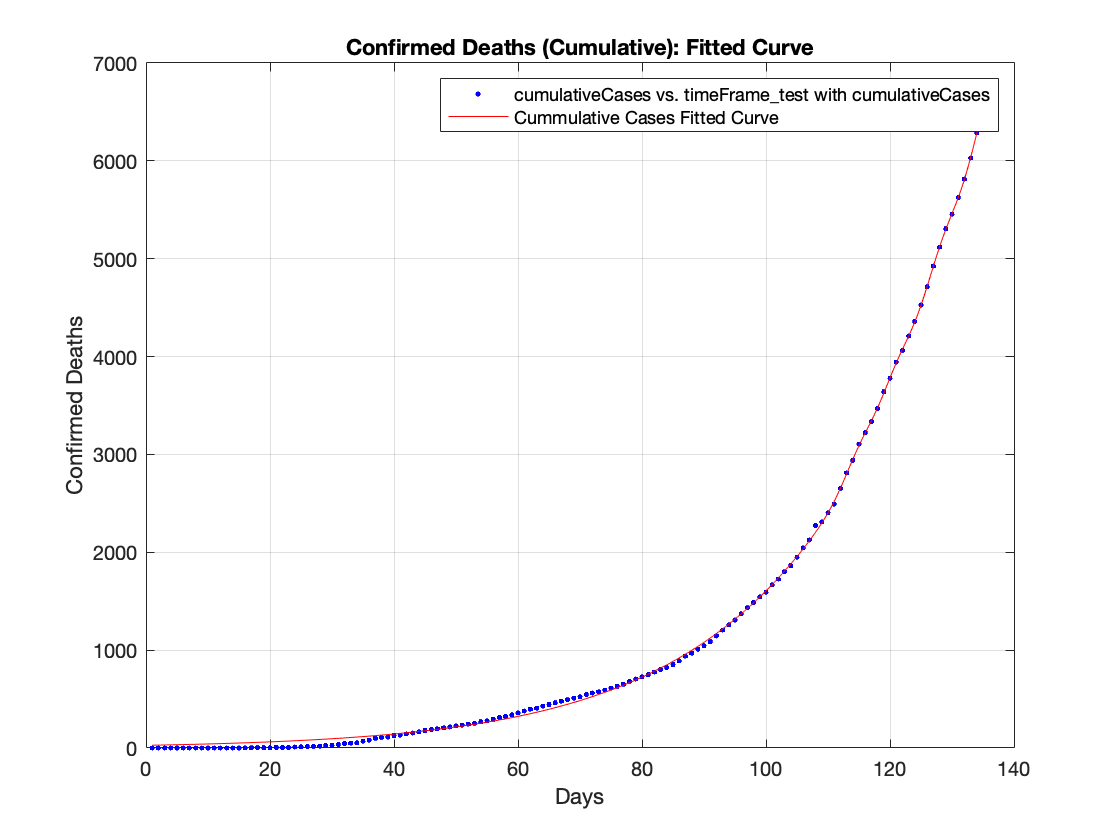

fittedCurve_cumulativeDeaths = createFit(timeElapsed, totalDeaths);
xlabel('Days'), ylabel('Confirmed Deaths'), title('Confirmed Deaths (Cumulative): Fitted Curve')

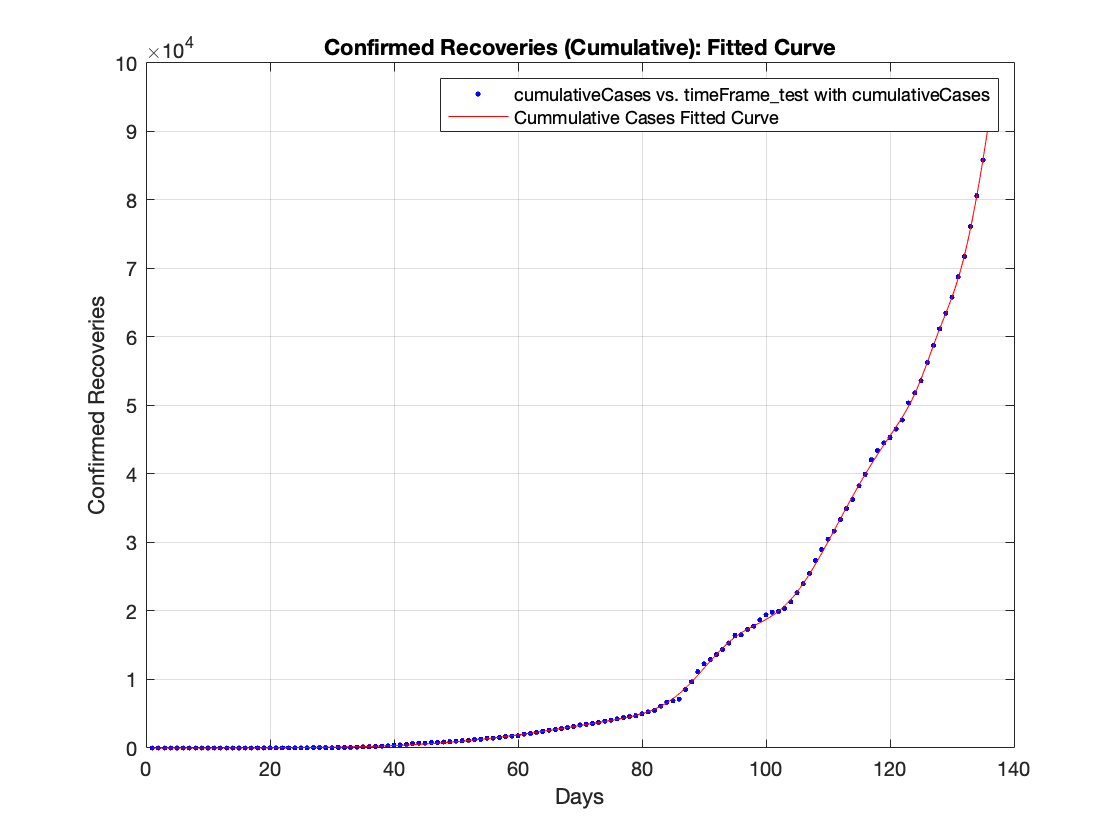

fittedCurve_cumulativeRecoveries = createFit(timeElapsed, totalRecoveries);
xlabel('Days'), ylabel('Confirmed Recoveries'), title('Confirmed Recoveries (Cumulative): Fitted Curve')

## 4. SEIR Compartment Epidemiological Model

- S is the fraction of susceptible individuals (those able to contract the disease).

- E is the fraction of exposed individuals (those who have been infected but are not yet infectious).

- I is the fraction of infective individuals (those capable of transmitting the disease).

- R is the fraction of recovered individuals (those who have become immune).

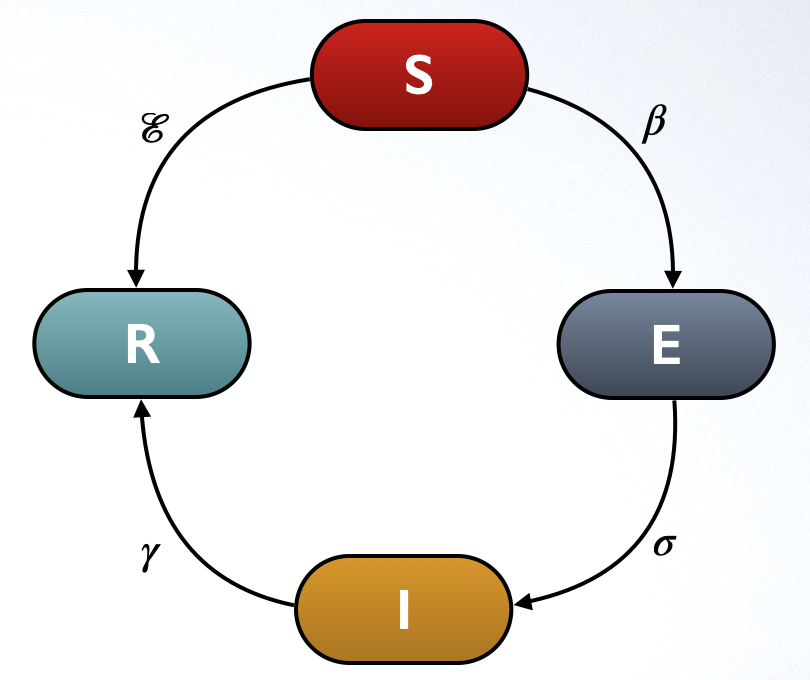


$$\frac{dS}{dt}=-\frac{S(t)}{N}Z-\beta\frac{S(t)I(t)}{N}+ VIi+VIe-\frac{VIi+VIe}{N}S(t)-\frac{R(t)-\gamma I(t)-\epsilon S(t)}{\mu d} u(t-t_v)$$



$$ \frac{dE}{dt}=\beta S(t)\frac{I(t)}{N} - \sigma E(t)-\frac{VIi+VIe}{N}E(t)$$



$$\frac{dI}{dt}=\sigma E(t) - \gamma I(t)-\frac{VIi+VIe}{N}I(t)$$



$$\frac{dR}{dt}=\gamma I(t)+\alpha V(t)$$



$$ \frac{dV}{dt}= \frac{R(t)-\gamma I(t)-\epsilon S(t)}{\mu d} u(t-t_v) - \alpha V(t)$$


## 5. SimBiology Model Data

SimBiology is an app developed by MATLAB which provides tools to model, simulate, and analyse dynamic systems while focusing on pharmacokinetic/pharmacodynamic (PK/PD) and systems biology applications. 

We chose to use this software package since it has a block diagram editor precisely designed for building models which is really intuitive. This software uses ordinary differential equations and stochastic solvers to simulate the time course of the model considering all of its parameters introduced in the equations such as the susceptible population, the virus reproduction number ir the typical time until removal amongst others.

This tool also incorporates analysis tools which allow to perform things such as sensitivity analysis or parameter sweeps to explore the influence of parameters and conditions on model behaviour.

### 5.1. Model Parameters

#### 5.1.1. Zoonotic Force before Market Opening

marketClosureData = data(1:93,:);                                       % Filter data before June 15th, 2020
ZoonoticForce_before = round(mean(marketClosureData.NUEVOS_CASOS))      % COVID-19 Zoonotic Force before June 15th, 2020

ZoonoticForce_before = 409

#### 5.1.2. Zoonotic Force before Market Opening

marketOpeningData = data(93:end,:);                                     % Filter data after June 15th, 2020
ZoonoticForce_after = round(mean(marketOpeningData.NUEVOS_CASOS))       % COVID-19 Zoonotic Force after June 15th, 2020  

ZoonoticForce_after = 3651

### 5.2. SimBiology Model Evaluation

The code below compares the results obtained from the SimBiology Model with the actual data regarding the infected population from day zero until the last data available (day 136).

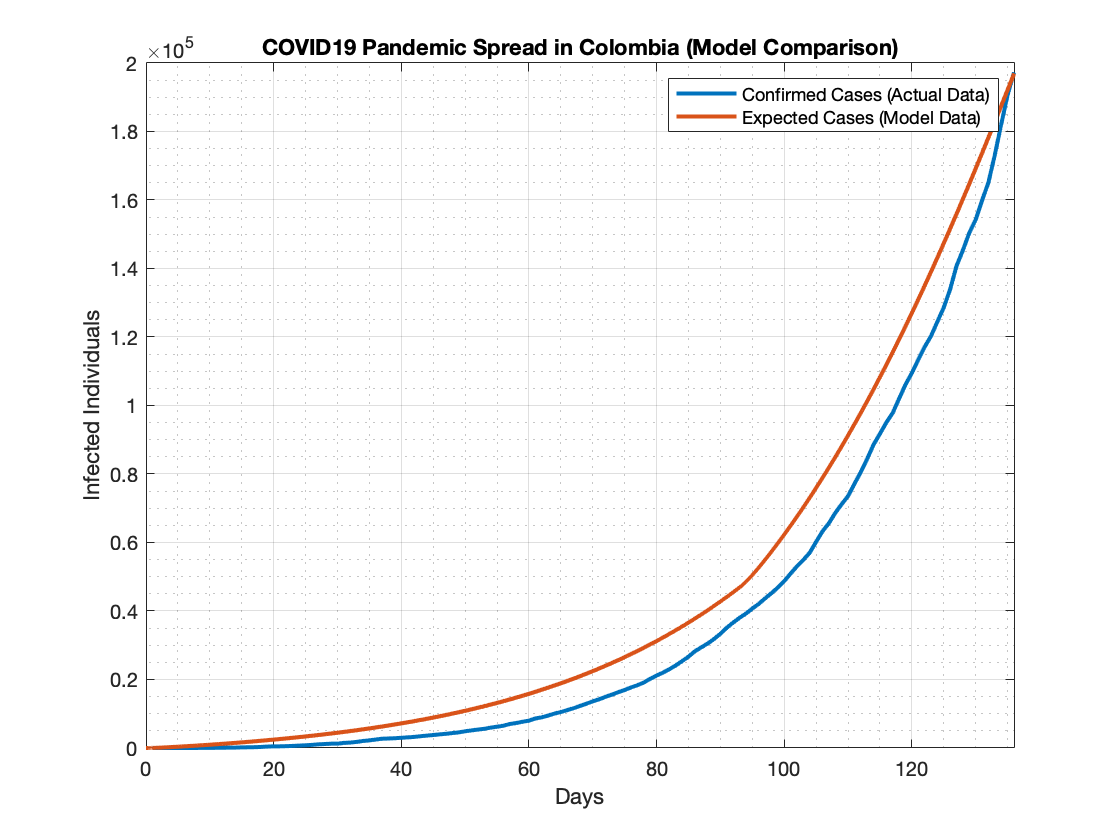

simulationTime = simbiologyModelResults(1).time;                        % SimBiology Simulation Results (Time Vector)
susceptible_modelData = simbiologyModelResults(1).Data(:,1);            % SimBiology Simulation Results (Susceptible Vector)
exposed_modelData = simbiologyModelResults(1).Data(:,2);                % SimBiology Simulation Results (Exposed Vector)
infected_modelData = simbiologyModelResults(1).Data(:,3);               % SimBiology Simulation Results (Infected Vector)

xAxis_limit = length(timeElapsed);                                      % Time Axis Upper Limit
simBiology_simulationTime = 800;                                        % SimBiology Simulation Time

figure;
plot(timeElapsed,totalInfections,  'LineWidth',2), hold on
plot(simulationTime, infected_modelData,  'LineWidth',2)
xlim([0,xAxis_limit]), ylim('auto')
xlabel('Days'), ylabel('Infected Individuals'), title('COVID19 Pandemic Spread in Colombia (Model Comparison)')
legend('Confirmed Cases (Actual Data)','Expected Cases (Model Data)')
grid on, grid minor

## 6. Conclusions

- The vaccine discovery and deployment was set to be 200 days after the first case is detected.

- Vaccine effectiveness is fixed to be 35% which is amongst the average effectiveness rate for influenza vaccines.

- According to the SEIR model proposed in SimBiology and the given parameters, the virus is set to be eradicated completely approximately 750 days after patient zero.

- The pandemic’s peak in Colombia is estimated to take place around day 190 after the first case in confirmed.

- The vaccination effect eliminates possible outbreaks of the virus after the peak of infection.

## 7. References

[1]    J. T Wu, K. Leung and G. M Leung, "Nowcasting and forecasting the potential domestic and international spread of the 2019-nCoV outbreak originating in Wuhan, China: a modelling study", *The Lancet*, 2020. [Online]. Available: https://www.thelancet.com/action/showPdf?pii=S0140-6736%2820%2930260-9. [Accessed: 10- Jul- 2020].

[2]    Q. Lin et al., "A conceptual model for the coronavirus disease 2019 (COVID-19) outbreak in Wuhan, China with individual reaction and governmental action", *IJID Online*, 2020. [Online]. Available: https://www.ijidonline.com/article/S1201-9712(20)30117-X/fulltext#%20. [Accessed: 10- Jul- 2020].

[3]    C. Sun and Y. Hsieh, *ScienceDirect*, 2020. [Online]. Available: http://Global analysis of an SEIR model with varying population size and vaccination. [Accessed: 10- Jul- 2020].

[4]    "SimBiology", *MathWorks*. [Online]. Available: https://www.mathworks.com/products/simbiology.html. [Accessed: 06- Jul- 2020].

[5]    "SimBiology Tutorials for QSP, PBPK, and PK/PD Modeling and Analysis", *YouTube*. [Online]. Available: https://www.youtube.com/playlist?list=PLn8PRpmsu08pzgMRgXLuDPOZDTJRqoTKK. [Accessed: 06- Jul- 2020].